# はじめに

人手不足の昨今、『業務負荷の見える化』を求められてはいませんか。

だのに職場が古風で、プロジェクト管理ツールなど導入されてはいない。

あるいは導入されたプロジェクト管理ツールがイケてなくて、ぜんぜん定着していない。

そんな時、あなたならどうしますか？

私「うーん、予定はOutlookで管理してるから、そのデータを負荷の見える化にも使えないものか…」

私「…せや！MATLABで解決したらええんや！」

私「テキストディープラーニング使えば何か出来るやろ、[Advent Calendar](https://qiita.com/aoimidori/items/796db2e0ce90f64f30d1)にそういうのあったし。」

ということで、MATLABで解決していきます。

まず本稿では、Outlookから予定表をぶっこ抜くMATLABに持ってくるまでを示します。

なお、コードの大半は下記URLを参考に作成しています。

そのままだと動かなかったのでメンテしたり加筆したりしました。

[https://stackoverflow.com/questions/40429116/retrieving-outlook-calendar-items-using-matlab](https://stackoverflow.com/questions/40429116/retrieving-outlook-calendar-items-using-matlab)

またこの記事は井上さんのlivescript2markdownを使って作成しています、便利！

[https://github.com/minoue-xx/livescript2markdown](https://github.com/minoue-xx/livescript2markdown)

clear all;
close all;

## 1. Outlook APIに接続

下記コマンドを実行することで、MATLABからOutlook APIに接続します。

outlook = actxserver('Outlook.Application');
mapi = outlook.GetNamespace('mapi');

次に、GetDefaultFolderkメソッドを叩いてOutlookの所定のフォルダにアクセスします。

メソッドの引数とフォルダの対応表は下記URLを参考、予定表フォルダは「9」にあります。

[Baccho Log [WSH]Outlookの操作](https://baccholog.com/archives/128)

explorer = mapi.GetDefaultFolder(9).GetExplorer;

さらに掘り下げていくことで、個人用や共用の予定表を取得することが出来ます。

今回は個人用の予定表を取得してみましょう。

NavModule = explorer.NavigationPane.Modules.GetNavigationModule(1); %予定表を取得
NavGroup = NavModule.NavigationGroups.GetDefaultNavigationGroup(1);% 個人用の予定表を取得
%NavGroup = NavModule.NavigationGroups.GetDefaultNavigationGroup(2);% 共用の予定表を取得

## 2.特定の日時でフィルタする

『yyyy/MM/dd HH:mm』または『MM/dd/yyyy HH:mm』のフォーマットで日付を指定します。

HH:mmは省略可能ですが（その場合AM8:00ぐらいに指定？）変な結果が出ないよう省略しないのが吉です。

またフィルタは予定の開始時間あるいは終了時間で設定できます。開始時間でフィルタする場合は下記。

StartDate_MIN = '2020/02/05 00:00';
StartDate_MAX = '2020/02/06 23:00';

%[Start]は開始時間、[End]は終了時間をフィルタ条件として使用
filter = {['[Start] >= ''',StartDate_MIN,''' AND [Start] <= ''', StartDate_MAX, '''']};

## 3.予定を取得、MATLABのテーブルに成型する

取得の対象となるOutlook予定表は下記です。

フィルタ条件を2/5~2/6に指定したので、「家族と朝ごはん」以降の予定が取れれば成功です。

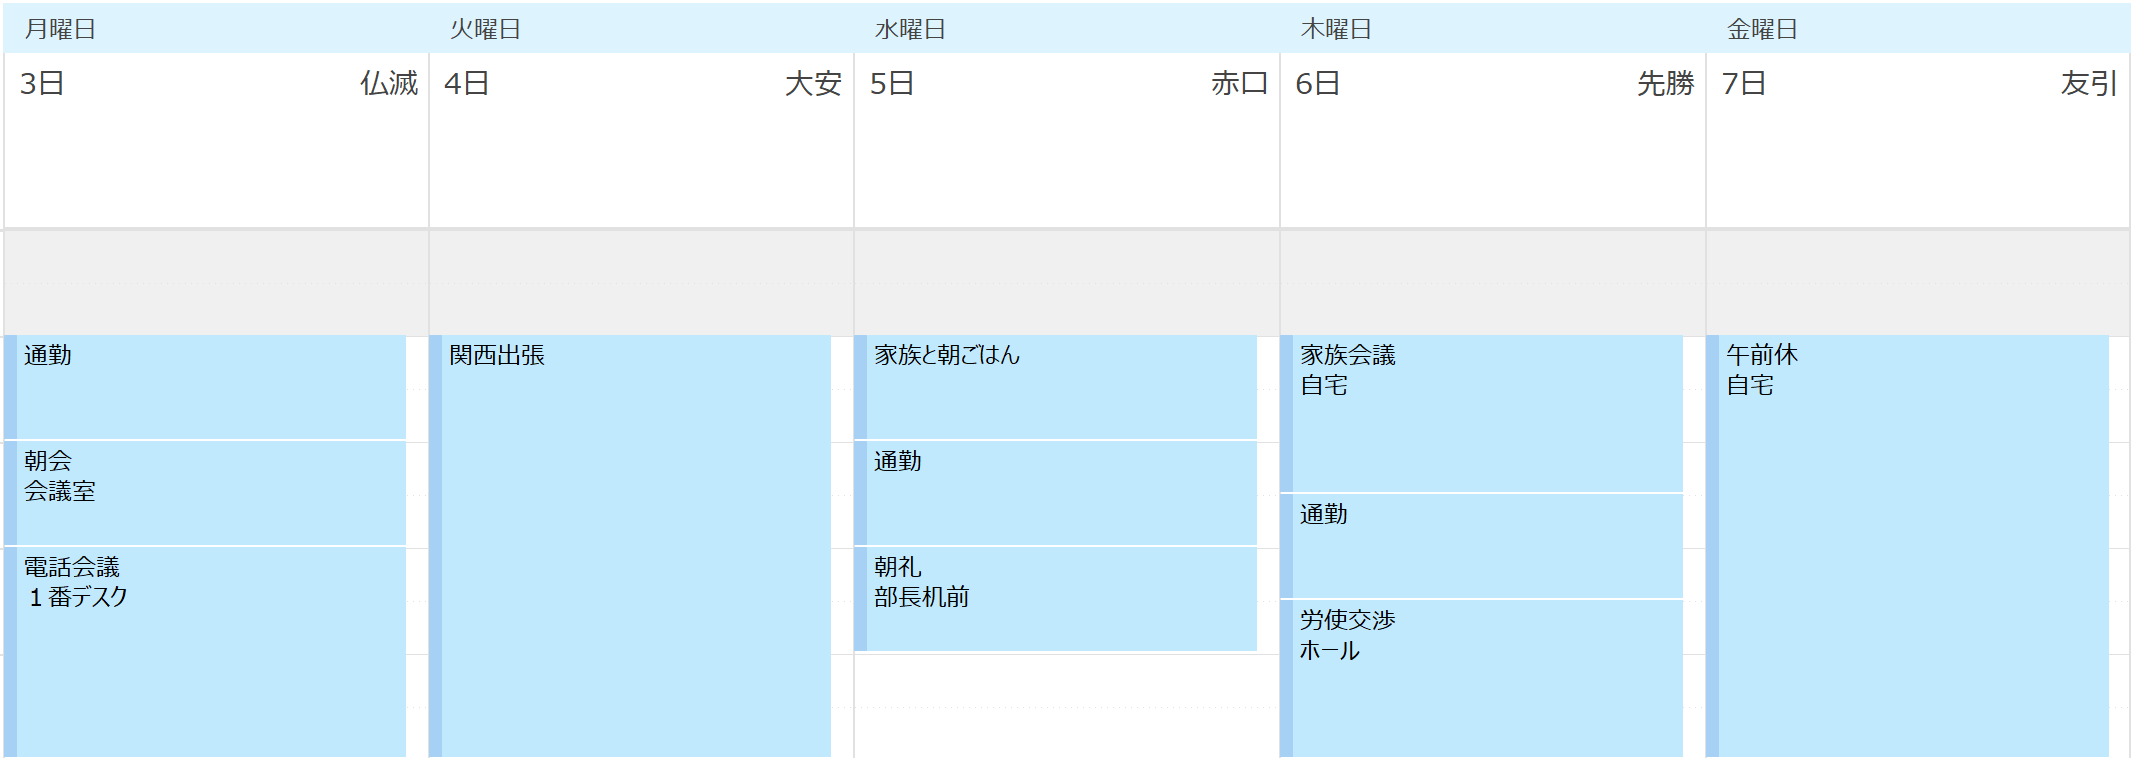

取得およびテーブルの成型は下記。

テーブル成型は色々なやり方があるとは思いますが、今回の場合はこれが一番可読性が高いかなと。

for i=1:NavGroup.NavigationFolders.Count
    NavFolder = NavGroup.NavigationFolders.Item(i);
    LST = NavFolder.Folder.Items;
    %LST.IncludeRecurrences = -1;
    LST.Sort('[Start]');
    LST_Restrict = LST.Restrict(filter{1});
    Cnt = LST_Restrict.Count;
    sz = [Cnt 3];
    varNames = {'Subject','Start','End'};
    varTypes = {'string','datetime','datetime'};
    Calendar_Table = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames);
    for j = 1:Cnt
        Calendar_Table.Subject(j) = LST_Restrict.Item(j).Subject;
        Calendar_Table.Start(j) = LST_Restrict.Item(j).Start;
        Calendar_Table.End(j) = LST_Restrict.Item(j).End;
    end
end

Calendar_Table

Calendar_Table = 6×3 table
       Subject               Start                   End        
    ______________    ___________________    ___________________

    "家族と朝ごはん"    2020/02/05 08:00:00    2020/02/05 09:00:00
    "通勤"            2020/02/05 09:00:00    2020/02/05 10:00:00
    "朝礼"            2020/02/05 10:00:00    2020/02/05 11:00:00
    "家族会議"         2020/02/06 08:00:00    2020/02/06 09:30:00
    "通勤"            2020/02/06 09:30:00    2020/02/06 10:30:00
    "労使交渉"         2020/02/06 10:30:00    2020/02/06 12:00:00


やったぜ。

## 4.予定の長さを計算する

最終ゴールが「業務負荷の見える化」なので、それぞれの予定の長さが知りたいですね。

MATLABさんは気が利いているので、下記にて簡単に計算可能です。

Calendar_Table.Duration = Calendar_Table.End - Calendar_Table.Start

Calendar_Table = 6×4 table
       Subject               Start                   End            Duration
    ______________    ___________________    ___________________    ________

    "家族と朝ごはん"    2020/02/05 08:00:00    2020/02/05 09:00:00    01:00:00
    "通勤"            2020/02/05 09:00:00    2020/02/05 10:00:00    01:00:00
    "朝礼"            2020/02/05 10:00:00    2020/02/05 11:00:00    01:00:00
    "家族会議"         2020/02/06 08:00:00    2020/02/06 09:30:00    01:30:00
    "通勤"            2020/02/06 09:30:00    2020/02/06 10:30:00    01:00:00
    "労使交渉"         2020/02/06 10:30:00    2020/02/06 12:00:00    01:30:00
